## **Session Data**

### **KingKong.01898**

- Premininary data collecting on 02/05/2020, **with perturbation**

- Targets (m): [0, 0.10], [0 0.05]

- Force Threshold (N): 10, 20

- Comment: extremely hard on short direction with high force threshold, failure a lot of trials. 

% read the session
ss1898 = SessionScan(1898);

Loading raw FT and WAM...


% trial count on each combo
taskScanTrials(ss1898);
% figures of mean trial
axhf = plotMeantrialForce(ss1898);
axhp = plotMeantrialPosVel(ss1898);
axhv = plotMeantrialVel(ss1898);

### **KingKong.01910**

- Preliminary data collecting on 02/09/2020, no perturbation

- Targets (m): [0, 0.10], [0 0.05]

- Force Threshold (N): 10, 20

- Comment: extremely hard on short direction with high force threshold, failure a lot of trials. 

% read the session
ss1910 = SessionScan(1910);
% trial count on each combo
taskScanTrials(ss1910);
% figures of mean trial
axhf = plotMeantrialForce(ss1910);
axhp = plotMeantrialPos(ss1910);
axhv = plotMeantrialVel(ss1910);

### **KingKong.01912**

- Preliminary data collecting on 02/09/2020, no perturbation

- Targets (m): [0, 0.10], [0 0.05]

- Force Threshold (N): 10, 20

- Comment: Much easier whey I sit down, arm curved 30cm before right sholder 

% read the session
ssnum = 1912;

% read data
fObjectName = ['ss' num2str(ssnum)];
if exist(fObjectName,'var')==0
    eval([fObjectName '= SessionScan(' num2str(ssnum) ');']);
end

Loading raw FT and WAM...
FT High Sample...
WAM High Sample...
Trialfy...


Index exceeds the number of array elements (0).

Error in interp1 (line 153)
        extrapMask = Xq < X(1) | Xq > X(end);

Error in TrialScan/predictImpedanceLinDev (line 188)
                fce_ = interp1(fce_t, fce, t_all); 

Error in 

% trial count on each combo
taskScanTrials(ss1912);

FT: 10N, Dist: 0.05m, trials: 30 / 30
FT: 10N, Dist: 0.10m, trials: 31 / 33
FT: 20N, Dist: 0.05m, trials: 30 / 33
FT: 20N, Dist: 0.10m, trials: 30 / 31


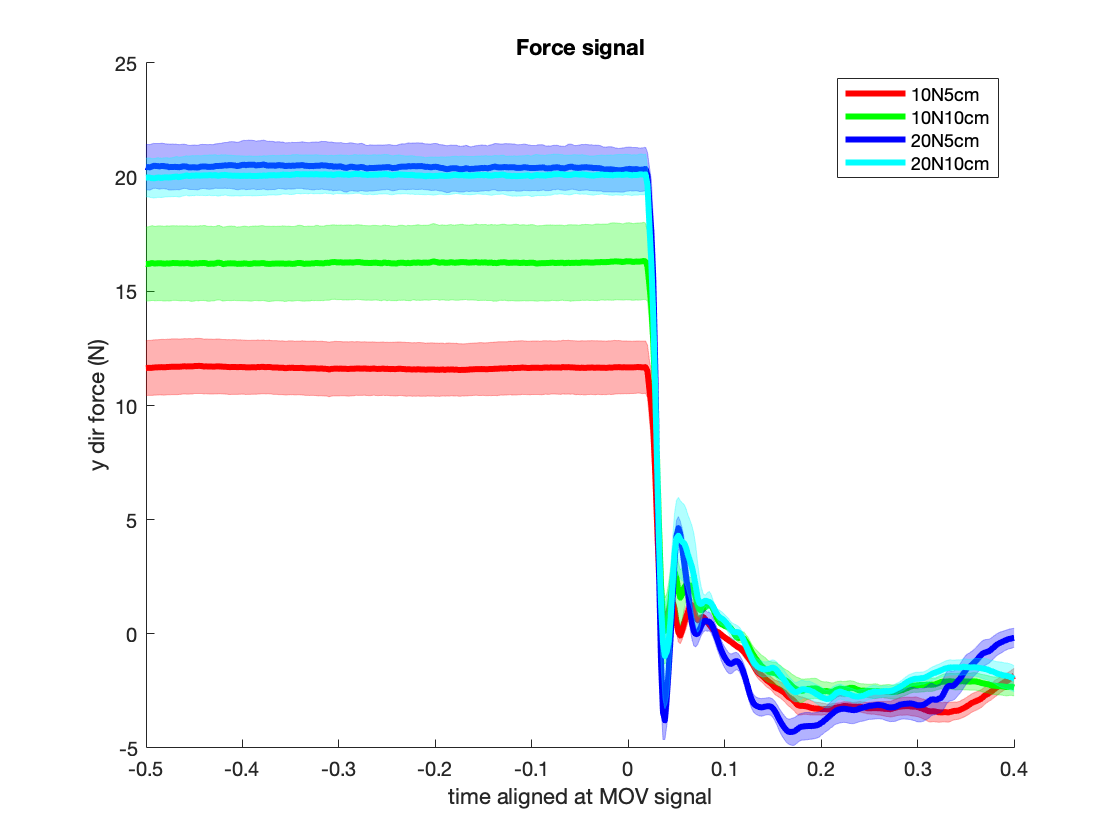

% figures of mean trial
axhf = plotMeantrialForce(ss1912);

Enter function Resample;


Enter function Resample;


Enter function Resample;


Enter function Resample;


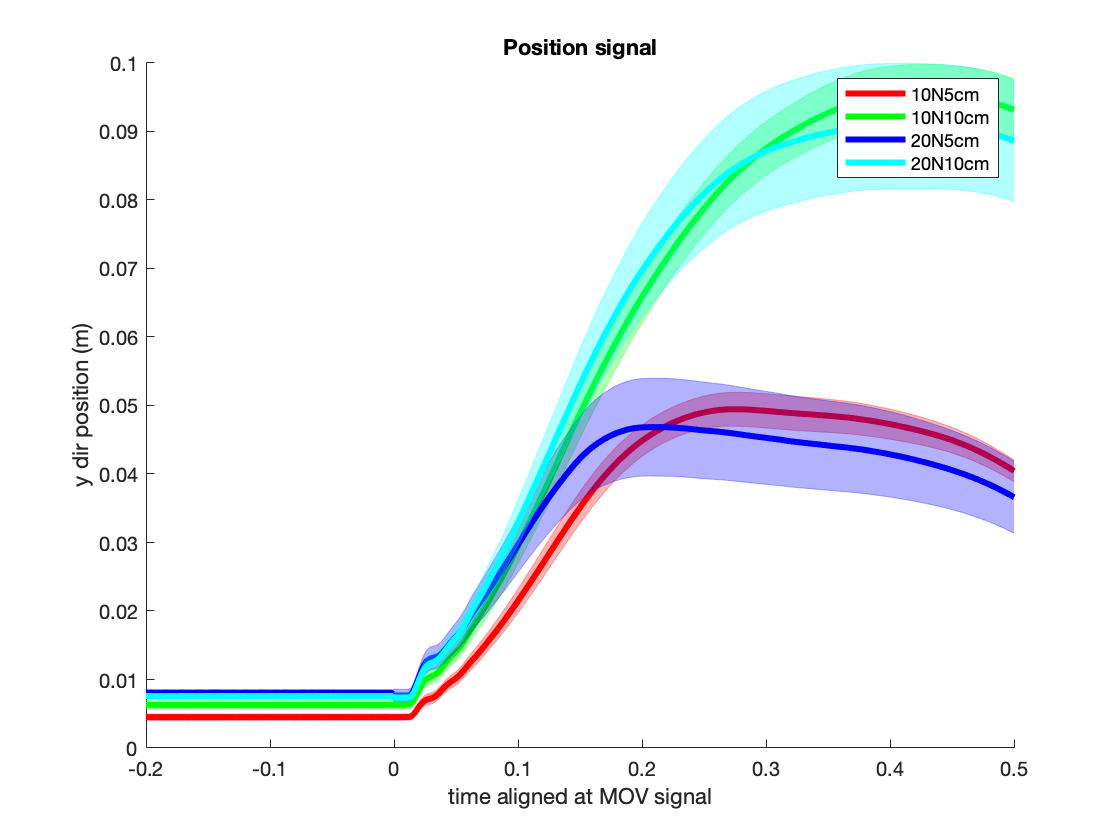

axhp = plotMeantrialPos(ss1912);

Enter function Resample;


Enter function Resample;


Enter function Resample;


Enter function Resample;


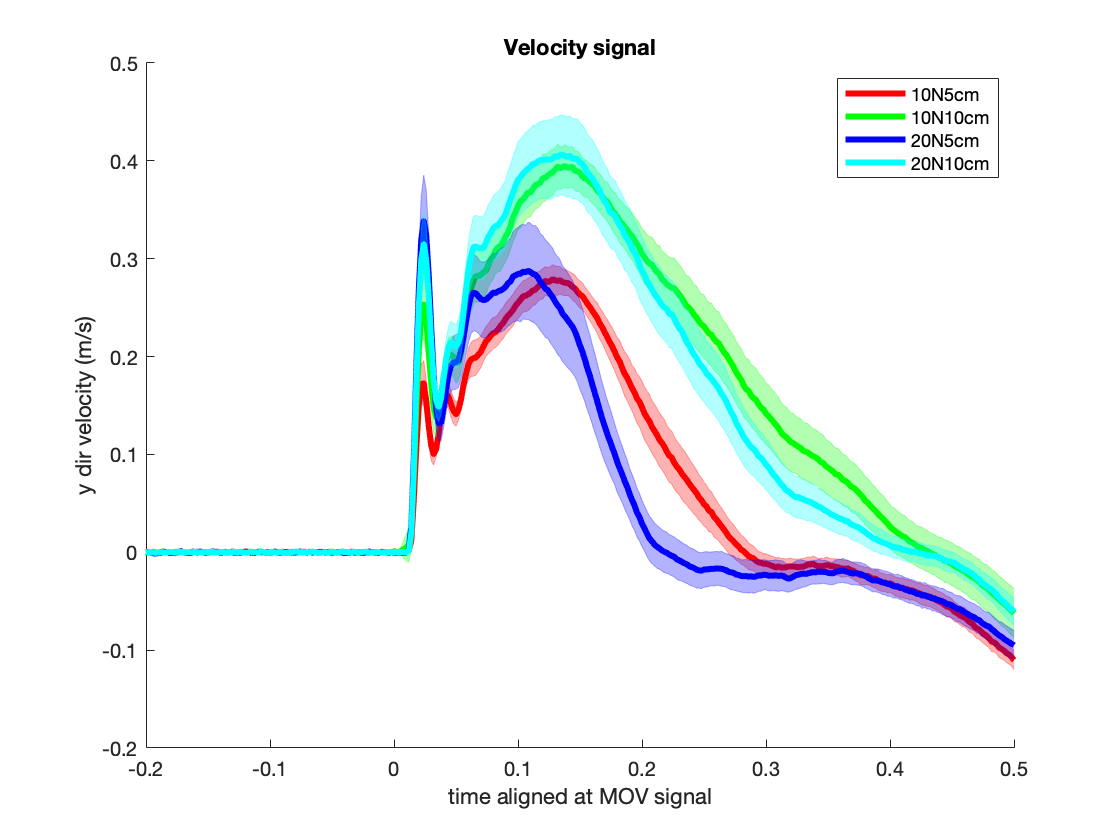

axhv = plotMeantrialVel(ss1912);

% read the session
ssnum = 1913;

% read data
fObjectName = ['ss' num2str(ssnum)];
if exist(fObjectName,'var')==0
    eval([fObjectName '= SessionScan(' num2str(ssnum) ');']);
end

Loading raw FT and WAM...
FT High Sample...
WAM High Sample...
Trialfy...
  05%...  10%...  15%...  20%...pos_ and fce_ have nan values, abort!
  25%...  30%...  35%...  40%...  45%...  50%...  55%...pos_ and fce_ have nan values, abort!
  60%...  65%...  70%...  75%...  80%...  85%...  90%...  95%...  100%...  100%  FINISHED!


% trial count on each combo
taskScanTrials(ss1913);

FT: 10N, Dist: 0.05m, trials: 30 / 30
FT: 10N, Dist: 0.10m, trials: 31 / 33
FT: 20N, Dist: 0.05m, trials: 30 / 32
FT: 20N, Dist: 0.10m, trials: 30 / 32


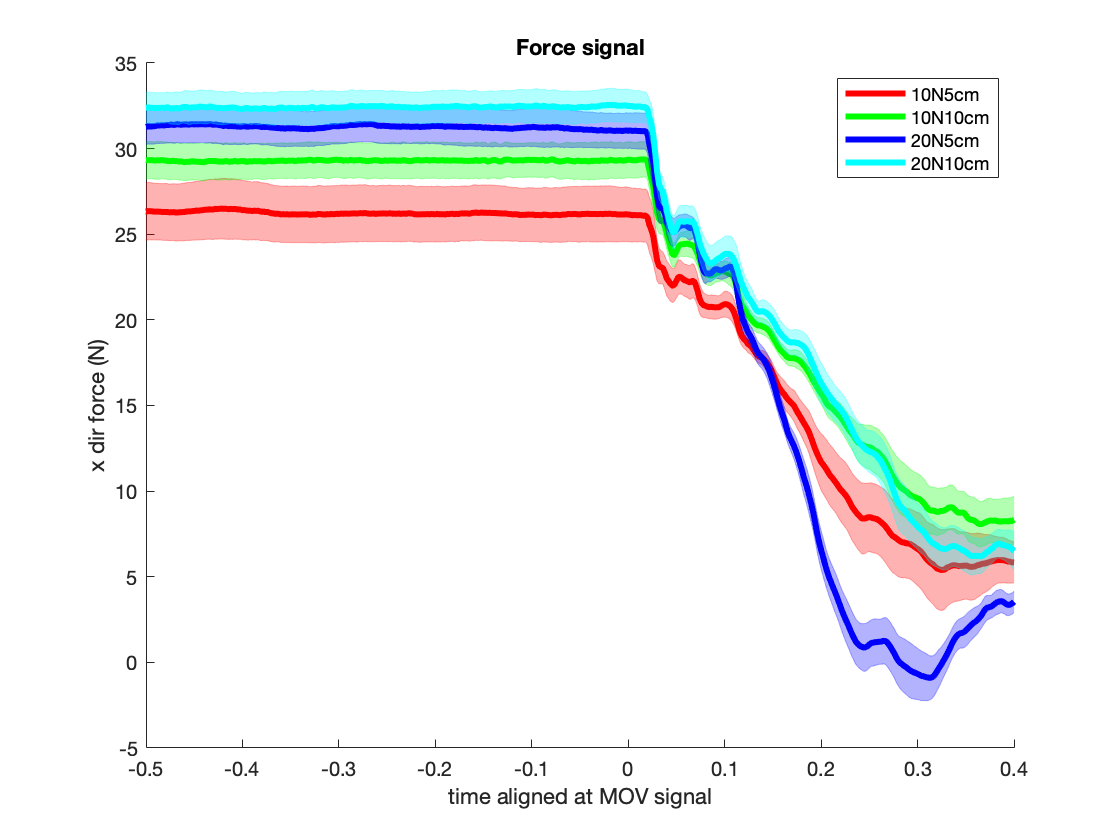

% figures of mean trial
axhf = plotMeantrialForce(ss1913);

Enter function Resample;


Enter function Resample;


Enter function Resample;


Enter function Resample;


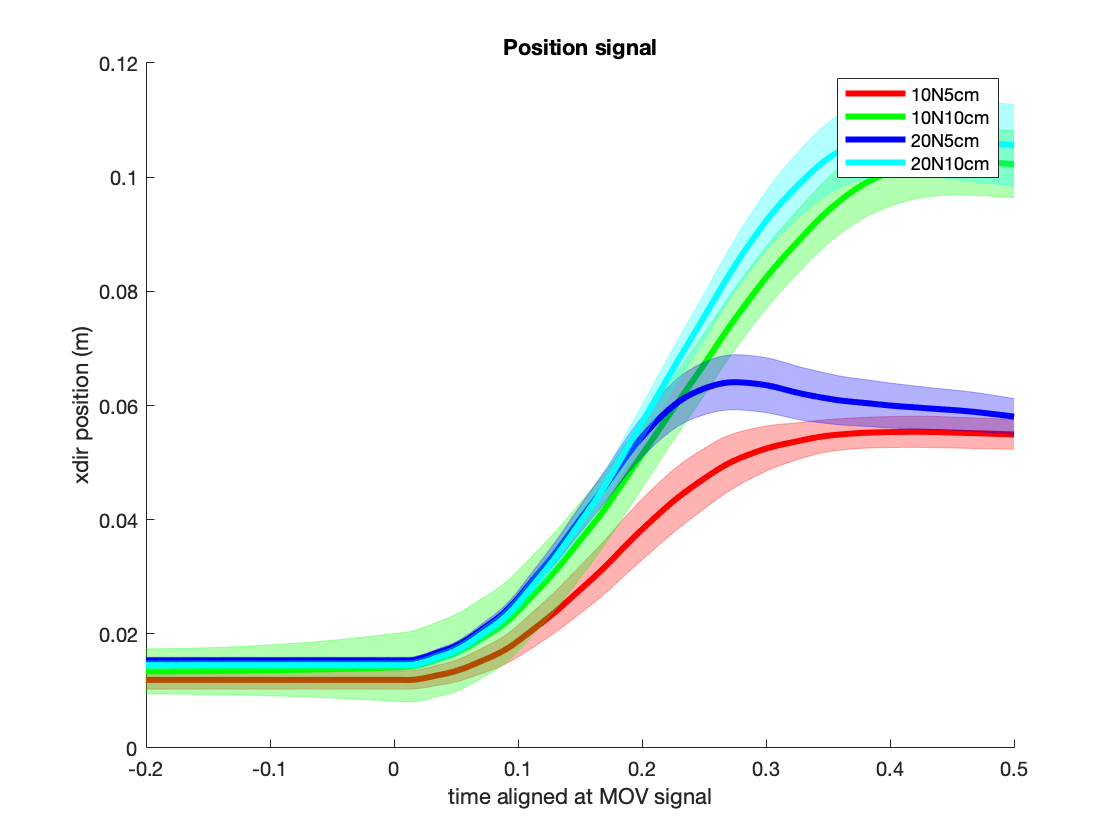

axhp = plotMeantrialPos(ss1913);

Enter function Resample;


Enter function Resample;


Enter function Resample;


Enter function Resample;


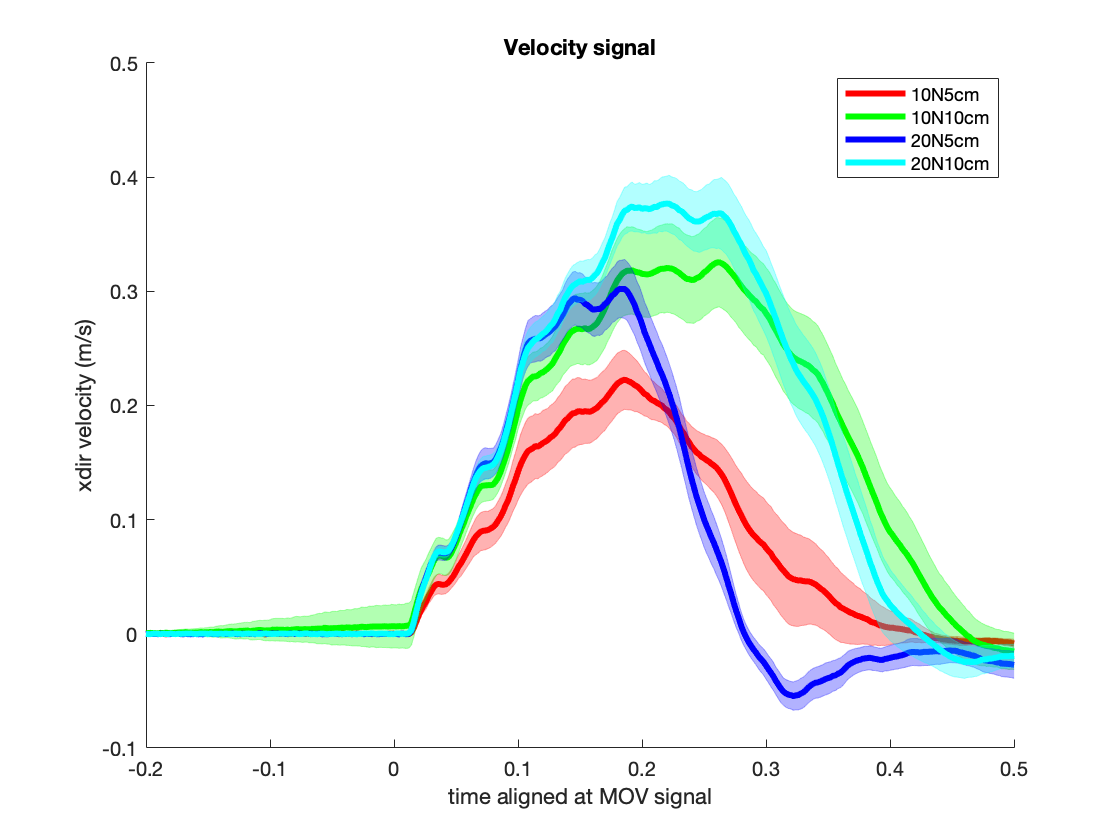

axhv = plotMeantrialVel(ss1913);

## Sanity Check certain session:

Sanity check should include: 

- Trial finish condition (color label each trial sucess/failure);   - Just see how the subject works on trials;

- Force baseline plot. - See if force baseline has changed significantly during trials. If exist, means force measurement are erroneous; 

- Original task curves on specific task. - To check each trial and the trial variance. (Q: how to see each trial according to their line?)

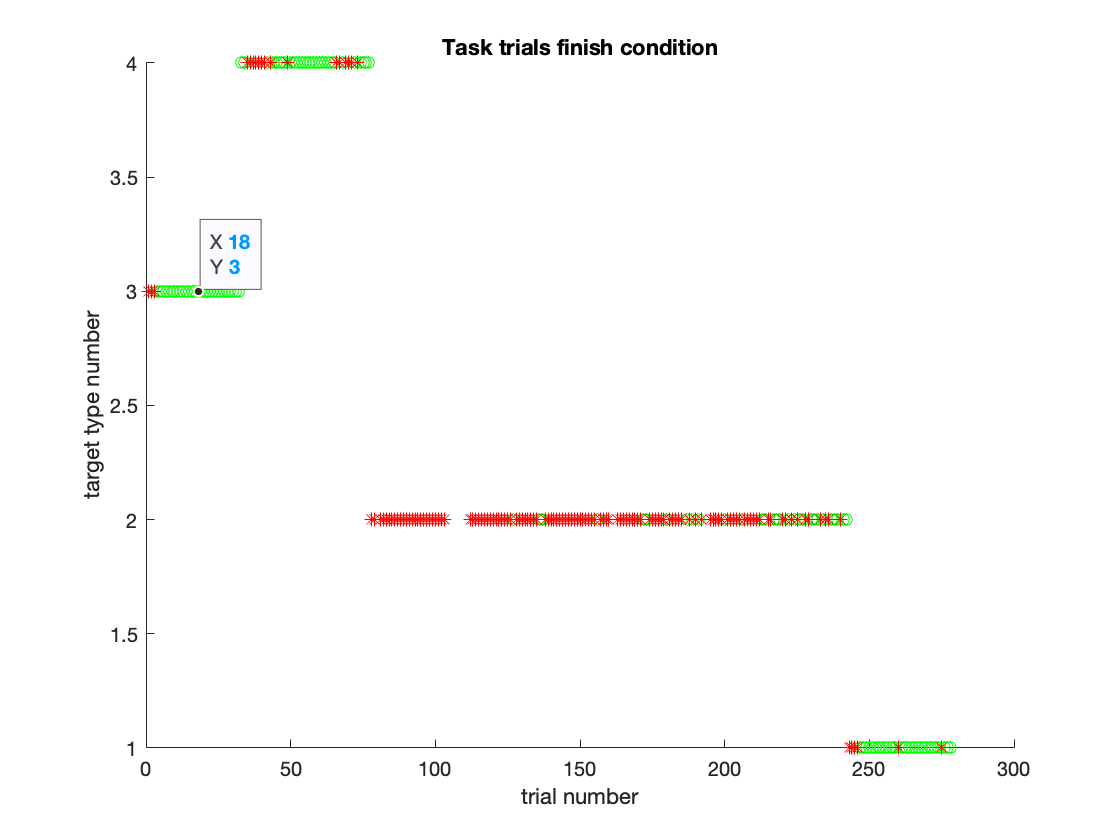

axh =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [361 279 560 420]
       Units: 'pixels'

  Show all properties


% specify session
ssnum = 1898;
% read data
fObjectName = ['ss' num2str(ssnum)];
if exist(fObjectName,'var')==0
    eval([fObjectName '= SessionScan(' num2str(ssnum) ');']);
end
% 1. Trial Finish Condition
axh = eval(fObjectName).plotTaskTrialFinish()

% 2. Force Baseline Plot

% 3. Original Curve on each trial